# ライン検出器を学習

JetBotのカメラから収集した画像を使い目標座標(x, y)を推定する回帰モデルを再学習する。

## 初期化

clear; close all; clc; rng('default');

## ラベリング用の動画生成

動画ファイル(xxxx.avi)をラベリング用の動画(xxxx_for_labeler.mp4)に変換

% 動画一覧を取得
videoDS = fileDatastore('.','FileExtensions','.avi','ReadFcn',@(file)vision.VideoFileReader(file));

% 動画ファイルごとに処理
for k = 1:numel(videoDS.Files)
    [dirname,filename,ext] = fileparts(videoDS.Files{k});

    writeFilename = fullfile(dirname,[filename,'_for_labeler.mp4']);
    if ~exist(writeFilename,'file')
        % 動画書き込みオブジェクトの設定
        videoWriter = vision.VideoFileWriter(writeFilename,...
            'FileFormat','MPEG4','Quality',90);

        % 動画読み込みオブジェクト
        videoReader = vision.VideoFileReader(videoDS.Files{k});
        videoReader.VideoOutputDataType = 'uint8';

        % 動画を逐次読み込んで最初のラベリング点を描画
        while ~videoReader.isDone
            I = videoReader();
            % 目印となる円を描画
            I = insertShape(I,"FilledCircle",[size(I,2)/2, size(I,1)-10,5],"Color","red");
            % コメントを描画
            I = insertText(I,[size(I,2)/2+5, size(I,1)-10],"←最初にここをクリック",...
                "AnchorPoint","leftCenter","Font","MS PGothic","TextColor","red");
            % 動画を書き出し
            videoWriter(I);
        end

        % 動画をファイナライズ
        release(videoWriter);
    end
end

## ラベリング

ラベラー用のMP4を開いてアノテーション。

アノテーション結果はexportedLabels2.matなど異なるファイル名で保存すること。

% videoLabeler('trainVideo_for_labeler.mp4');

## ファイル名を指定

動画とラベルデータのファイル名を指定する

fileNames = {'exportedLabels.mat',...
    'exportedLabels2.mat',...
    'exportedLabels3.mat',...
    'exportedLabels4.mat'};
doTraining = true;
doDesignWithDND = false;

## 動画から画像を抽出

### ラベルデータの読み込み

ワークスペース変数にラベルデータをロード

parentFolder = fullfile(pwd,'dataset');
[~,~] = rmdir(parentFolder,'s');
Y = [];
for k = 1:numel(fileNames)
    d = load(fileNames{k});
    videoName = d.gTruth.DataSource.Source;
    % ファイル名の置き換え
    videoName = char(strrep(string(videoName),"_for_labeler.mp4",".avi"));

### ラベルデータ保存用のフォルダを作成

    [~,filename,~] = fileparts(videoName);
    dataFolder = fullfile(parentFolder,filename);
    [~,~,~] = rmdir(dataFolder,'s');
    [~,~,~] = mkdir(dataFolder);

### ラベリングした目標座標の座標を抽出

    labelData = d.gTruth.LabelData.WhiteLine;
    validVideoIndex = ~cellfun(@isempty,d.gTruth.LabelData.WhiteLine);
    labelData = labelData(validVideoIndex);
    Ytmp = zeros(length(labelData),2);
    for i = 1:length(labelData)
        Ytmp(i,:) = labelData{i}{1}(end,:);
    end
    Y = [Y; Ytmp];

ラベル付けされている静止画を抜き出し、画像ファイルとして保存

    v = VideoReader(videoName);
    wh = [v.Width v.Height];

    videoIndex = find(validVideoIndex);
    for l = 1:numel(videoIndex)
        video = read(v,videoIndex(l));
        imwrite(video,fullfile(dataFolder,num2str(int32(l),'image_%05d.png')));
    end
end

% 可視化する
imds = imageDatastore(parentFolder,'IncludeSubfolders',true);
figure;
montage(imds);

% 目標座標が画像中心を原点とし、長い辺が[-1 1]になるように正規化
Y = (Y - wh(1)/2) ./ (wh(1)/2)

## データセットを学習用とテスト用に分ける

rng(0);
shuffledIndices = randperm(imds.numpartitions);
idx = length(shuffledIndices) - 4; % 4枚をテスト用にする
trainImds = imageDatastore(imds.Files(shuffledIndices(1:idx)));
testImds = imageDatastore(imds.Files(shuffledIndices(idx+1:end)));
trainArrayDs = arrayDatastore(Y(shuffledIndices(1:idx),:));
testArrayDs = arrayDatastore(Y(shuffledIndices(idx+1:end),:));

% 画像と目標座標を結合
trainDs = combine(trainImds,trainArrayDs);
testDs = combine(testImds,testArrayDs);
preview(trainDs)

## 目標座標を画像上に表示し意図通り抽出できているか確認

目標座標(赤丸)が意図通りの場所にない場合には一つ前の演習でラベリング結果を再度確認する。

numPreview = 4; % 最初の枚

imgData = cell(numPreview,1);
trainDs.reset;
for k = 1:numPreview
    data = read(trainDs);
    pos = data{2} .* (wh(1)/2) + wh(1)/2;
    imgData{k} = insertShape(data{1,1}, 'FilledCircle', [pos 5],'Color','Green');
end
figure
montage(imgData, 'BorderSize', 10)

## 学習データの水増し(Augmentation)

データを水増しして、様々なシーンの画像を疑似的に生成する。今回は収束を早めるため画像の反転のみを入れる。

augTrainDs = transform(trainDs, @augmentData);

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augTrainDs);
    pos = data{1,2} .* (wh(1)/2) + wh(1)/2;
    augmentedData{k} = insertShape(data{1,1}, 'FilledCircle', [pos 5],'Color','Green');
    reset(augTrainDs);
end
figure
montage(augmentedData, 'BorderSize', 10)

## 回帰用のネットワークを準備

if doDesignWithDND
    deepNetworkDesigner
else
    net = resnet18;
    lgraph = layerGraph(net);
    meanVal = lgraph.Layers(1).Mean;
    stddivVal = lgraph.Layers(1).StandardDeviation;
    lgraph = replaceLayer(lgraph,'data',imageInputLayer([wh([2 1]),3],'Name','data',...
        'Normalization','zscore','Mean',meanVal,'StandardDeviation',stddivVal));
    lgraph = replaceLayer(lgraph,'fc1000',fullyConnectedLayer(2,'Name','new_fc'));
    lgraph = removeLayers(lgraph,'prob');
    lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',regressionLayer('Name','regressionoutput'));
    lgraph = connectLayers(lgraph,'new_fc','regressionoutput');
    lgraph_1 = lgraph;
end

## 学習用のオプションを設定

`MaxEpochs`: 学習データセットを何回使うか。学習が収束していない場合は回数を増やす。

`InitialLearnRate`: 初期学習率。上げると学習が早くなるが発散しやすい。小さいと時間はかかるが精度が上がりやすい。

`LearnRateDropFactor`: 学習率を何倍にするか。

`LearnRateDropPeriod`: 何エポック経過したら学習率を下げるか。

options = trainingOptions('adam',...
    'MiniBatchSize',32,...
    'MaxEpochs',50,...
    'InitialLearnRate',1e-3,...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',25, ...
    'Shuffle','every-epoch',...
    'ResetInputNormalization',false,...
    'Verbose',true,...
    'Plots','training-progress');

## ネットワークの学習

学習例：

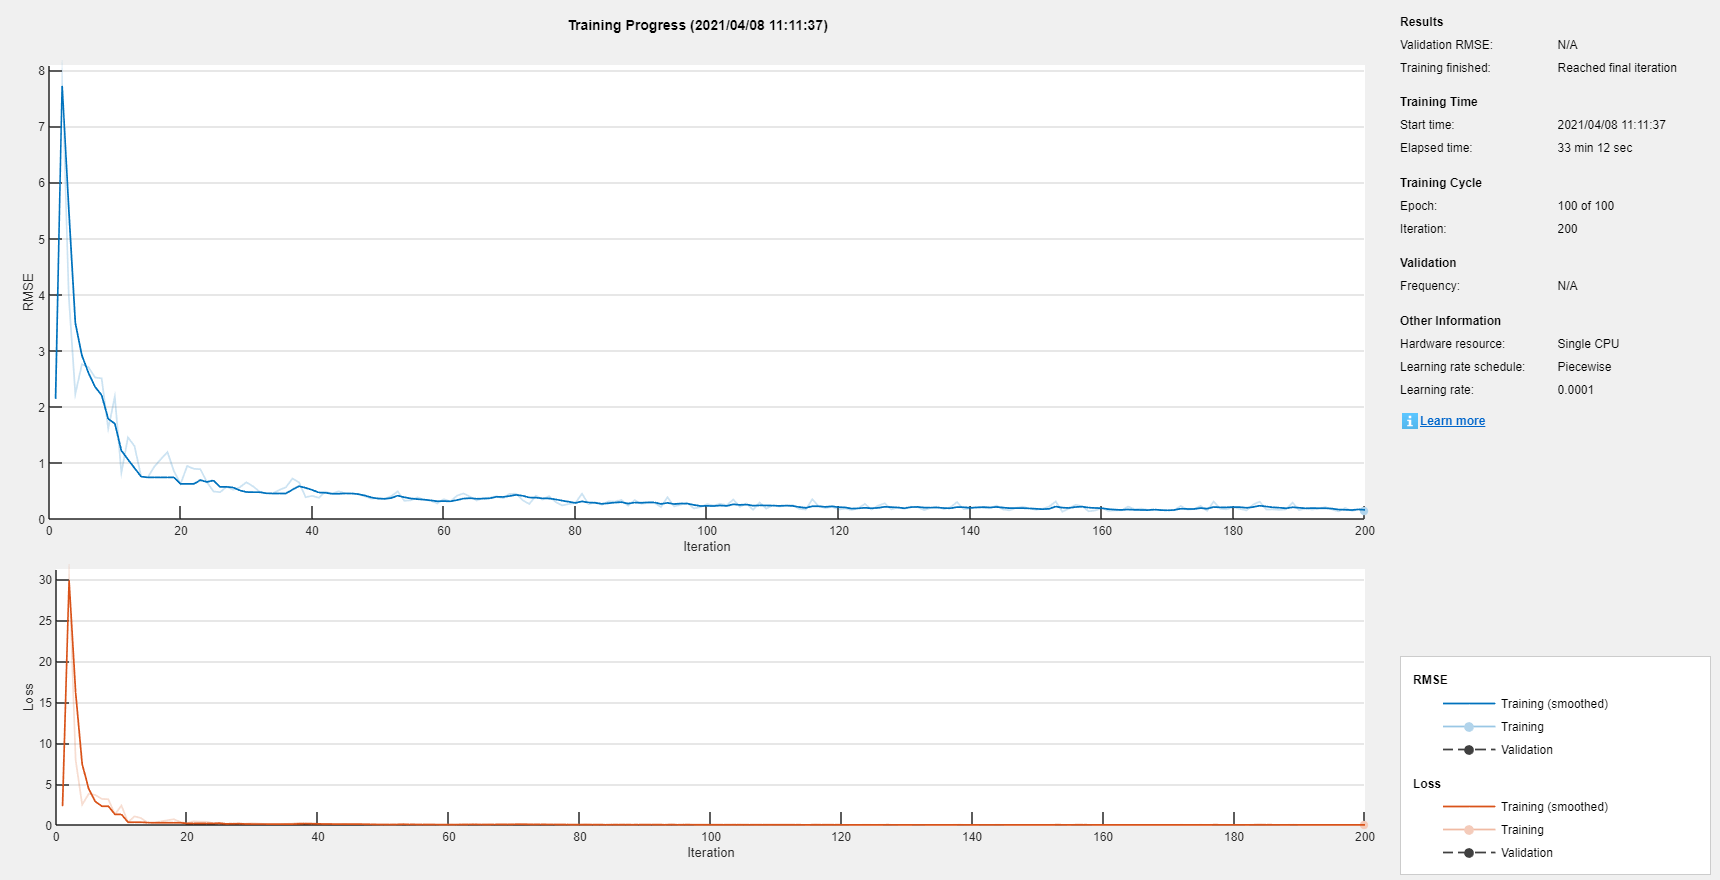

if doTraining
    rng('default');
    trainedNet = trainNetwork(augTrainDs,lgraph_1,options);

    % 学習結果を保存
    save('mynet_new','trainedNet');
else
    load('mynet.mat');
end

## 学習に使っていないデータでテスト

testDs.reset;
testData = cell(testDs.numpartitions,1);
for k = 1:testDs.numpartitions
    data = read(testDs);
    imdata = data{1};
    posGt = data{2};
    pos = predict(trainedNet,imdata);
    pos = pos .* (wh(1)/2) + wh(1)/2;
    posGt = posGt .* (wh(1)/2) + wh(1)/2;
    testData{k} = insertShape(imdata, 'FilledCircle', [pos 5],'Color','Green');
    testData{k} = insertShape(testData{k}, 'FilledCircle', [posGt 5],'Color','Red');
end
figure
montage(testData, 'BorderSize', 10)
title('予測結果(緑=予測、赤=真値)');

function data = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    pos = A{ii,2};
    sz = size(I);

    if numel(sz) == 3 && sz(3) == 3
        I = jitterColorHSV(I,...
            'Contrast',[0.2 0.8],...
            'Hue',0.05,...
            'Saturation',0.1,...
            'Brightness',0.2);
    end

    % Blur
    %     LEN = rand*5;
    %     THETA = rand*2*pi;
    %     PSF = fspecial('motion', LEN, THETA);
    %     I = imfilter(I, PSF, 'conv', 'circular');

    % Randomly flip image.
    tform = randomAffine2d('XReflection',true);
    %     ,...
    %         'Scale',[0.8 1.2],...
    %         'Rotation',[-10 10]);
    rout = affineOutputView(sz,tform,'BoundsStyle','centerOutput');
    I = imwarp(I,tform,'OutputView',rout);

    % Apply same transform to boxes.
    pos = tform.transformPointsForward(pos);

    data(ii,:) = {I, pos};
end
end

*Copyright 2021 The MathWorks, Inc.*